# Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

In the space below, define the problem statement:

- This project utilizes MATLAB to analyze lithium-ion battery charging using a specified dataset. This involves fitting the given voltage equation to the battery profile, modeling relevant quantities such as voltage, current, and power to express the movement of energy through a circuit, and computing analytical results. By the end of this project, we will have estimated tau, determined the necessary time for the battery to reach 80% and 100% charge, and computed results regarding energy and power, including resistive energy loss. 

List the requirements, constraints, and success criteria for the project:

- The requirements of this project are importing the battery dataset, fitting the voltage equation to the charging model, plotting voltage vs. time, current vs. time, and power vs. time graphs, estimating tau, calculating rate of voltage change over specific time intervals, computing time required to reach 80% and 100% charge, using integration to calculate total energy delivered to the battery, estimating power and energy loss, and summarizing results using a table.

- This project is constrained by the provided battery dataset and software limitations. All requirements must be fulfilled using the MATLAB live script, and all data must be derived from the imported dataset. Additionally, several computations in this code hinge upon estimations rather than strictly formulaic calculations. The voltage equation must also be assumed to be an appropriate and accurate approximation of the lithium-ion battery profile. We must also work collaboratively and make time to meet frequently despite busy schedules.

- Success criteria for this project entail completing all the requirements while adhering to the above constraints. All code must run without error and effectively answer all questions, and team members must be able to pinpoint and thoroughly explain their contribution to the project. 

What is your proposed solution?

- Our proposed solution is to complete tasks individually using the MATLAB live script template and collaborate to ensure a quality, complete project. We will complete tasks in order and maintain regular communication.

List the steps you will need to take to achieve your proposed solution:

- Complete teamwork agreement and establish team responsibilities

- Complete MATLAB summer bridge course to build familiarity with MATLAB software

- Maintain communication through Discord and meet regularly to keep up with deadlines 

- Complete tasks sequentially and collaboratively conduct quality assurance 

- Review completed project, make necessary edits, and proofread all material

- Compile data in a final presentation or live script

What challenges do you face in the process of achieving the solution?

- We face challenges with using MATLAB software to complete tasks, as this is a relatively new skill for most of us. Certain tasks, such as producing goodness-of-fit statistics and utilizing calculus functions, may prove to be difficult. Additionally, we must manage our own schedules to meet with one another and ensure tasks are punctually completed. Time must be well-managed and due dates must be met. Code must be thoroughly proofread and edited, which requires strict attention to detail and team coordination.

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\textrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

% STEP 1: Load the example battery dataset

dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");
head(data,10000);

    Data_Point    Test_Time           DateTime          Step_Time     Step_Index    Cycle_Index       Current         Voltage     Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy        dV/dt         Internal_Resistance    Temperature
    __________    __________    ____________________    __________    __________    ___________    ______________    _________    _______________    __________________    _____________    ________________    ______________    ___________________ 

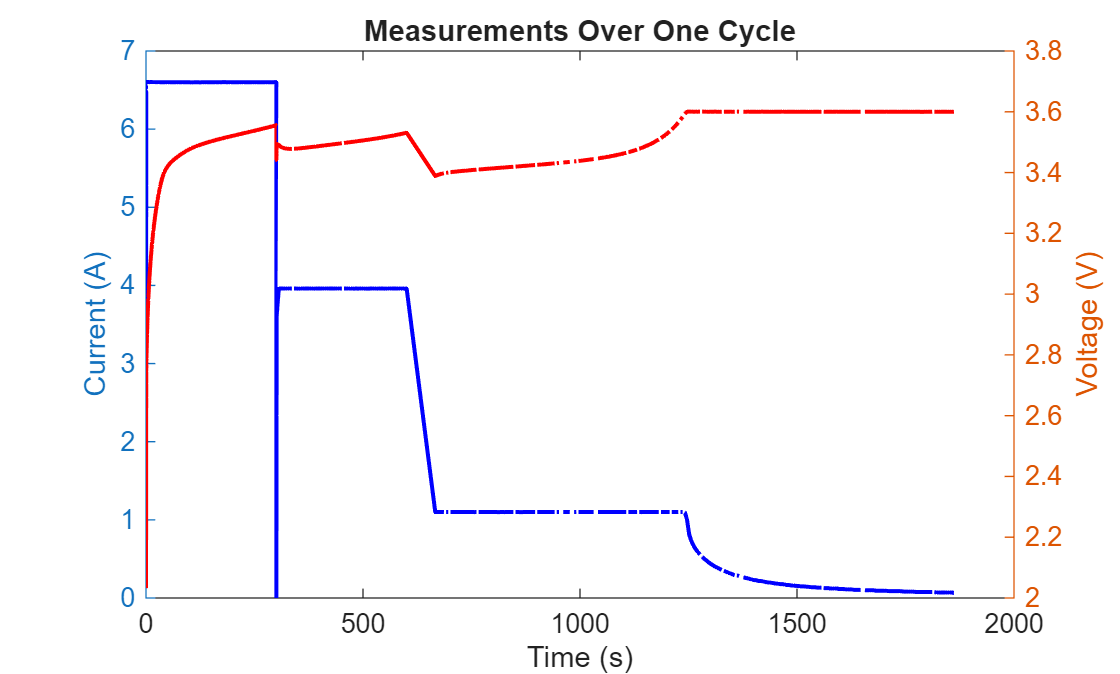


% STEP 2: Pre-process the data to focus on a single cycle, and the period of time
% within that cycle that the battery was being charged

cycleData = data(data.Cycle_Index == 1, :); 
cycleData = cycleData(cycleData.Current > 0, :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));

figure;

yyaxis left;
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current (A)');

yyaxis right;
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
xlabel("Time (s)");

title('Measurements Over One Cycle');

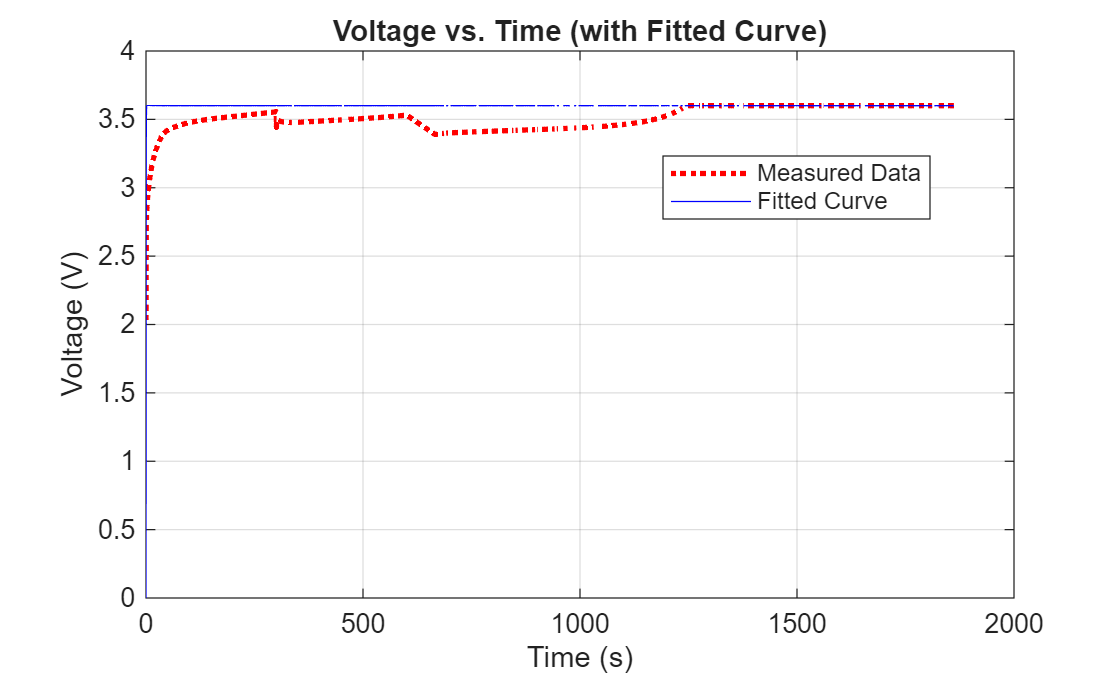


% STEP 3: Follow the provided workflow to fit the voltage equation to your selected
% data. Hint: Vmax is known, so the only unknown in the equation is RC (also
% known as tau, the RC time constant - it is equivalent to the time it takes
% for a capacitor to reach ~63.2% of its max voltage). When you are fitting
% the curve to the data, you are essentially estimating the unknown
% parameter, tau.

voltage = cycleData.Voltage;
time = cycleData.DateTime;
Vmax = cycleData.Voltage(end); 

VTau = 0.632 * Vmax;

indexTau = find(voltage >= VTau, 1);

starting = time(indexTau);

fo = fitoptions('Method', 'NonlinearLeastSquares', ...
        'StartPoint', starting);

ft = fittype('Vmax * (1 - exp(-time/tau))', ...
    'independent', 'time', ...
    'coefficients', 'tau', ...
    'problem', 'Vmax', ...
    'options', fo);

[f, gof] = fit(time, voltage, ft, 'problem', Vmax);

fittedCurve = f(time);

% STEP 4: Plot the data and the fitted curve in the same figure.

figure;

plot(time, voltage, '-r', 'LineWidth', 2.0, 'LineStyle', ':');
xlabel("Time (s)");
ylabel("Voltage (V)");
title("Voltage vs. Time (with Fitted Curve)");

hold on;

plot(time, fittedCurve, '-b');

legend("Measured Data", "Fitted Curve", "Location", "best");
grid on;


% STEP 5: Display the goodness-of-fit statistics.

tau = f.tau;

disp("Goodness of Fit Statistics:")

Goodness of Fit Statistics:



fprintf("Tau = %.4f seconds \n", tau)

Tau = 0.2278 seconds 


fprintf("SSE = %.4f \n", gof.sse)

SSE = 45.6541 


fprintf("R-Squared = %.4f \n", gof.rsquare)

R-Squared = 0.2290 


fprintf("DFE = %d \n", gof.dfe)

DFE = 611 


fprintf("Adjusted R-Squared = %.4f \n", gof.adjrsquare)

Adjusted R-Squared = 0.2290 


fprintf("RMSE = %.4f \n", gof.rmse)

RMSE = 0.2734 


## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

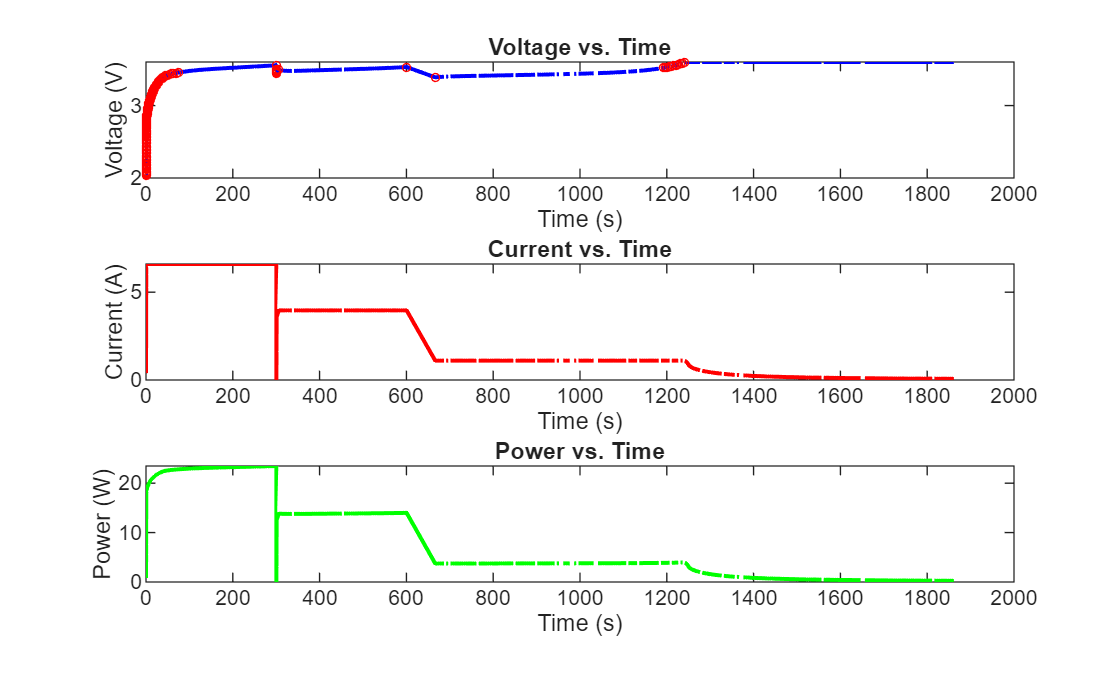


% STEP 1: Create a figure handle and initialize the first subplot. 
% Plot voltage vs. time.

figure;
subplot(3,1,1);

plot(time, voltage, '-b', 'LineWidth', 1.5);
xlabel("Time (s)");
ylabel("Voltage (V)");

title("Voltage vs. Time");

% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

dVdt = gradient(voltage, time);

slopeTolerance = 0.001;

notablePoints = find(abs(dVdt) > slopeTolerance);

hold on;

plot(time(notablePoints), voltage(notablePoints), 'ro', 'MarkerSize', 3)

% STEP 2: Use a second subplot to plot current vs. time.

current = cycleData.Current;

subplot(3,1,2);

plot(time, current, '-r', 'LineWidth', 1.5);
xlabel("Time (s)");
ylabel("Current (A)");

title("Current vs. Time");

% STEP 3: Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.

power = current .* voltage;

subplot(3,1,3);

plot(time, power, '-g', 'LineWidth', 1.5);
xlabel("Time (s)");
ylabel("Power (W)");

title("Power vs. Time");

## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 

interval1 = time >= 0 & time <= 100;
interval2 = time > 100 & time <= 300;
interval3 = time > 300 & time <= 600;
interval4 = time > 600 & time <= 1250;
interval5 = time > 1250 & time <= 1800;

% 0-100 s
time1 = time(interval1);
voltage1 = voltage(interval1);
dVdt1 = diff(voltage1) ./ diff(time1);
avg1 = mean(dVdt1);

% 100-300 s
time2 = time(interval2);
voltage2 = voltage(interval2);
dVdt2 = diff(voltage2) ./ diff(time2);
avg2 = mean(dVdt2);

% 300-600 s
time3 = time(interval3);
voltage3 = voltage(interval3);
dVdt3 = diff(voltage3) ./ diff(time3);
avg3 = mean(dVdt3);

% 600-1250 s
time4 = time(interval4);
voltage4 = voltage(interval4);
dVdt4 = diff(voltage4) ./ diff(time4);
avg4 = mean(dVdt4);

% 1250-1800 s
time5 = time(interval5);
voltage5 = voltage(interval5);
dVdt5 = diff(voltage5) ./ diff(time5);
avg5 = mean(dVdt5);

% dVdt Print

disp(" ")

disp("Average rate of voltage change:")

Average rate of voltage change:


fprintf("0-100 seconds: %.4f V/s \n", avg1)

0-100 seconds: 0.3856 V/s 


fprintf("100-300 seconds: %.4f V/s \n", avg2)

100-300 seconds: 0.0003 V/s 


fprintf("300-600 seconds: %.4f V/s \n", avg3)

300-600 seconds: -0.0107 V/s 


fprintf("600-1250 seconds: %.4f V/s \n", avg4)

600-1250 seconds: 0.0002 V/s 


fprintf("1250-1800 seconds: %.4f V/s \n", avg5)

1250-1800 seconds: -0.0000 V/s 



% STEP 2: Compute the time required to reach 80% charge and 100% charge

% Time to Reach 80% Charge

v80 = 0.80 * max(voltage);
indexV80 = find(voltage >= v80, 1);
time80 = time(indexV80);

% Time to Reach 100% Charge

[maxVoltage, timeMaxVoltage] = max(voltage);
time100 = time(timeMaxVoltage);

% Printing

disp(" ")

fprintf("Time to reach 80 Percent Charge: %.3f seconds \n", time80)

Time to reach 80 Percent Charge: 2.682 seconds 


fprintf("Time to reach 100 Percent Charge: %.3f seconds \n", time100)

Time to reach 100 Percent Charge: 1246.495 seconds 



% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

totalEnergy = trapz(time, power);

disp(" ")

fprintf("Total Energy Delivered to the Battery: %.3f Joules \n", totalEnergy)

Total Energy Delivered to the Battery: 14221.611 Joules 



% STEP 4: Estimate the resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.
% Calculate Resistance with Ohm's Law

resistance = cycleData.Internal_Resistance;

powerLoss = current.^2 .* resistance;
avgPowerLoss = mean(powerLoss);

allTime = time(end) - time(1);
energyLoss = avgPowerLoss * allTime;

disp(" ")

fprintf("Average Power Loss: %.3f Watts \n", avgPowerLoss)

Average Power Loss: 0.243 Watts 


fprintf("Resistive Energy Loss: %.3f Joules \n", energyLoss)

Resistive Energy Loss: 452.379 Joules 



format short g;

table(Vmax, tau, time80, time100, totalEnergy, avgPowerLoss, energyLoss, ...
    'VariableNames', {'MaximumVoltage(V)', 'Tau(s)', ...
    'TimeFor80PercentCharge(s)', 'TimeForFullCharge(s)', ... 
    'TotalEnergyDelivered(J)', 'AveragePowerLoss(W)', ...
    'ResistiveEnergyLoss(J)'})

ans = 1×7 table
    MaximumVoltage(V)    Tau(s)     TimeFor80PercentCharge(s)    TimeForFullCharge(s)    TotalEnergyDelivered(J)    AveragePowerLoss(W)    ResistiveEnergyLoss(J)
    _________________    _______    _________________________    ____________________    _______________________    ___________________    ______________________

         3.6001          0.22783             2.6823                     1246.5                    14222                   0.24302                  452.38        


## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

- Our results are highly practical and relevant in engineering. This project effectively demonstrates the charging cycle of a lithium-ion battery, which is widely used in commonplace objects like cell phones and electric cars. The analytical results displayed above are crucial in modeling characteristics such as charge, lifespan, safety, and efficiency of a lithium-ion battery. Computing charging times would benefit engineers striving to understand and maximize the lifespan of an electric car battery. Computing resistive energy loss would help engineers cut unnecessary losses and assess the efficiency of their systems. The tau value estimates how quickly the battery charges, information that may be used to improve user experience and overall charging times. These physical applications, among others, are demonstrated through our code. 

What are some limitations of your work?

- Our work is limited by the dataset provided and assumes that the voltage equation is an accurate model for lithium-ion battery charging. Our results are based on this singular dataset and thus may not adequately illustrate analytical results for all lithium-ion batteries, especially those of voltages higher than the 3.6 V provided. Some values calculated in this project, such as tau and resistive energy loss, are estimates derived using external formulas and are not expressly provided in the dataset. This dataset is assumed to be ideal and does not take into account several real-world factors such as resistor tolerance, circuit construction, temperature fluctuations, or miscellaneous error that may affect experimental results. 

What are practical next steps?

- Practical next steps would be to repeat this experiment under different conditions to evaluate the validity of the data provided. Additional quantities such as battery capacity and temperature may be factored into future trials in order to account for a broader spectrum of possibilities, creating a more comprehensive analysis of lithium-ion battery charging and improving the accuracy of estimates such as tau and energy loss values. Once the charging model has been perfected, engineers may use detailed datasets to improve battery life, refine charging cycles, and build towards future technological advancements. 